## Assignment 9

####     Part 1

slowmotion = load("slowmotion.mat");

IQ = slowmotion.iq;
s = slowmotion.s;
sm_framerate = s.Framerate_fps;
sm_depthIncrease_iq = s.iq.DepthIncrementIQ_m;
sm_startDepth_iq = s.iq.StartDepthIQ_m;
sm_num_beams_iq = s.iq.BeamsIQ;
sm_samples_iq = s.iq.SamplesIQ;
sm_frames_iq = s.iq.FramesIQ;
tissue = slowmotion.tissue;
sm_gain_iq = s.iq.feflowgain_dB;
sm_dyn_iq = s.iq.DynRange_dB;
sm_frsig = s.iq.frsIQ_Hz;


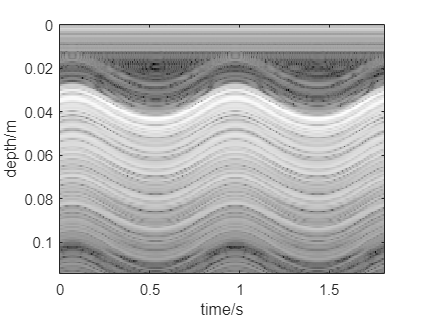

middle_beam = squeeze(IQ(:,4,:));
%since y axis is the samples and x axis is the frames
y_axis = sm_startDepth_iq:sm_depthIncrease_iq:(sm_samples_iq-1)*sm_depthIncrease_iq + sm_startDepth_iq;
x_axis = 0:1/sm_framerate:(sm_frames_iq-1)*1/sm_framerate;
%im = imagelog(abs(middle_beam),sm_gain_iq,sm_dyn_iq);
%imagesc(im, 'XData',x_axis,'YData',y_axis);
figure(1)
imagesc(x_axis, y_axis, 20*log10( abs( middle_beam) ) )
%caxis([-sm_dyn_iq 0]-sm_gain_iq)
%imagesc(20*log10(abs(middle_beam)),'XData',x_axis,'YData',y_axis);

%axis('image');
ylabel('depth/m');
xlabel('time/s');
axis on;
colormap(gray(255));

R = 0.0075; %in meter,estimated from the image
T = 0.9; %in seconds,estimated from the image
t0 = 1; %in seconds, estimated from the image
t = x_axis;
L = 0.1

L = 0.1000

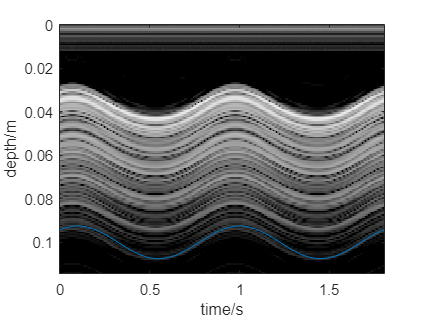

r = -R*cos(2*pi*(t-t0)/T) + L;
figure(2)
imagesc(x_axis, y_axis, 20*log10( abs( middle_beam) ) )
hold on;
dyn = 40;
gain = -90;
caxis([-dyn 0]-gain)
%imagesc(20*log10(abs(middle_beam)),'XData',x_axis,'YData',y_axis);
plot(t,r)
%axis('image');
ylabel('depth/m');
xlabel('time/s');
axis on;
colormap(gray(255));

#### Part 2

r_der = 2*pi*R/T *sin(2*pi*(t-t0)/T);

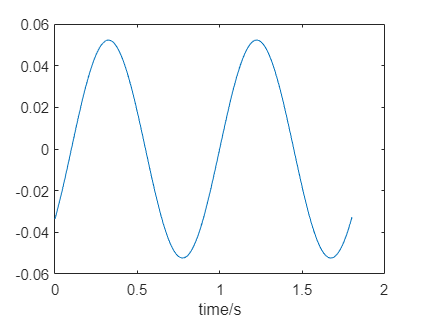

figure(3);
plot(t,r_der);
xlabel('time/s');

x = IQ(:,4,42);
y = IQ(:,4,43);

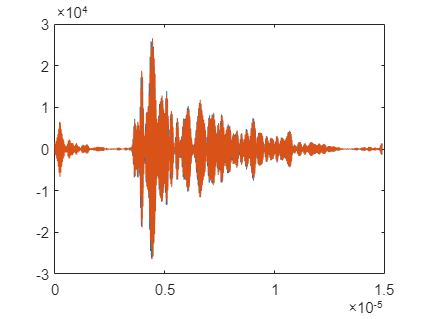

x_RF = iq2rf(x,s.iq.fDemodIQ_Hz,sm_frsig);
y_RF = iq2rf(y,s.iq.fDemodIQ_Hz,sm_frsig);
t_axis = 0:1/200e6:(2982-1)*1/200e6;
clf("reset");
figure(4);
plot(t_axis,x_RF);
hold on;
plot(t_axis,y_RF);

v_sm = (r_der(42)+r_der(43))/2

v_sm = 0.0069

The velocities for frame 42 is 14.6 mm/s and for 43 it is 15.5 mm/s. The radial displacement is 43.1 $\mu$m.

The timeshift between pulses is approx 71.3 ns


$$\Delta \Theta = 2 \pi\cdot 71.3 \cdot10^{-9} \cdot 2.5 \cdot 10^6 = 1.12 \quad \text{ rad}$$


EDIT:

Then the velocity is 0.0069 m/s

#### Part 3

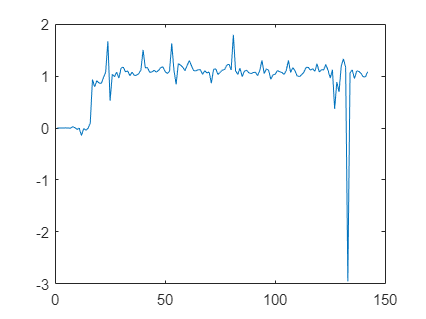

phase_shift = angle(conj(x).*y); %unsure whats ment by all axials samples
figure(5);
plot(phase_shift)

amplitude = abs(conj(x).*y)

amplitude = 	1.0e+08 *

    0.0142
    0.0456
    0.2188
    0.0813
    0.0161
    0.0033
    0.0238
    0.0102
    0.0073
    0.0074


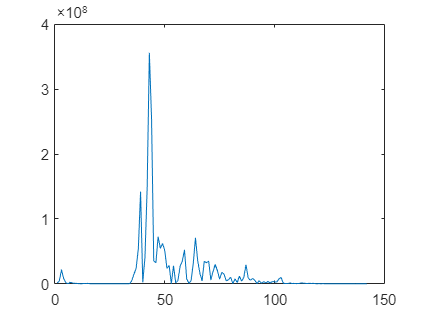

figure(12);
plot(amplitude)


estimate_sm = angle(mean(conj(x(30:50)).*y(30:50)));

From the code over the phaseshift is 1.9 rad.

EDIT: estimate is 1.102 rad.

With two scatters displaced by $\frac{\lambda}{4}$ will have a phaseshift of $\frac{\pi}{2}$, and the relation then becomes $v = \frac{\Delta \Theta F R_c}{4\pi f_0}$

R1est = conj(IQ(:,4,end-1)).*IQ(:,4,2:end);

f0 = 2.5e6;
v = R1est*sm_framerate/(4*pi*f0);
figure(13);
plot(v);

Error using plot
Data cannot have more than 2 dimensions.

#### Part 4

fastmotion = load("fastmotion.mat");

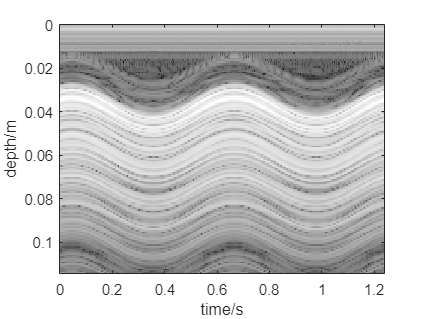

IQ_fm = fastmotion.iq;
f = fastmotion.s;
fm_framerate = f.Framerate_fps;
fm_depthIncrease_iq = f.iq.DepthIncrementIQ_m;
fm_startDepth_iq = f.iq.StartDepthIQ_m;
fm_num_beams_iq = f.iq.BeamsIQ;
fm_samples_iq = f.iq.SamplesIQ;
fm_frames_iq = f.iq.FramesIQ;
fm_tissue = fastmotion.tissue;
fm_gain_iq = f.iq.feflowgain_dB;
fm_dyn_iq = f.iq.DynRange_dB;
fm_frsig = f.iq.frsIQ_Hz;

middle_beam_fm = squeeze(IQ_fm(:,4,:));
%since y axis is the samples and x axis is the frames
y_axis_fm = fm_startDepth_iq:fm_depthIncrease_iq:(fm_samples_iq-1)*fm_depthIncrease_iq + fm_startDepth_iq;
x_axis_fm = 0:1/fm_framerate:(fm_frames_iq-1)*1/fm_framerate;
%im = imagelog(abs(middle_beam),sm_gain_iq,sm_dyn_iq);
%imagesc(im, 'XData',x_axis,'YData',y_axis);
figure(6)
imagesc(x_axis, y_axis, 20*log10( abs( middle_beam_fm) ) )
%caxis([-sm_dyn_iq 0]-sm_gain_iq)
%imagesc(20*log10(abs(middle_beam)),'XData',x_axis,'YData',y_axis);

%axis('image');
ylabel('depth/m');
xlabel('time/s');
axis on;
colormap(gray(255));

R = 0.0075; %in meter,estimated from the image
T = 0.65; %in seconds,estimated from the image
t0 = 0.65; %in seconds, estimated from the image
t = x_axis_fm;
L = 0.1

L = 0.1000

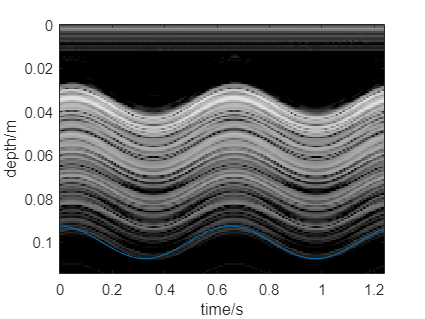

r = -R*cos(2*pi*(t-t0)/T) + L;
figure(7)
imagesc(x_axis, y_axis, 20*log10( abs( middle_beam_fm) ) )
hold on;
dyn = 40;
gain = -90;
caxis([-dyn 0]-gain)
%imagesc(20*log10(abs(middle_beam)),'XData',x_axis,'YData',y_axis);
plot(t,r)
%axis('image');
ylabel('depth/m');
xlabel('time/s');
axis on;
colormap(gray(255));

r_der = 2*pi*R/T *sin(2*pi*(t-t0)/T);

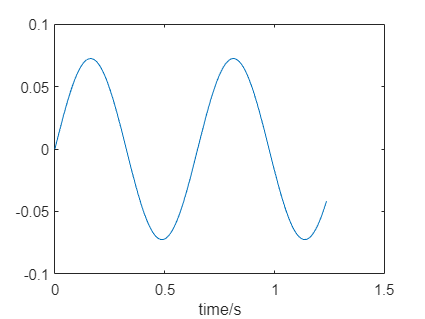

figure(8);
plot(t,r_der);
xlabel('time/s');

x_fm = IQ_fm(:,4,42);
y_fm = IQ_fm(:,4,43);

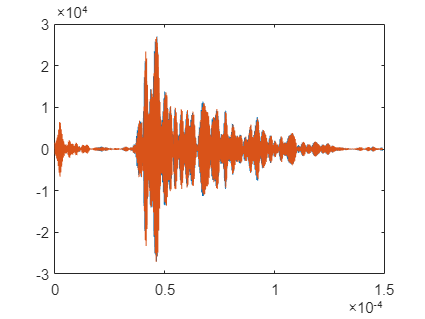

x_RF_fm = iq2rf(x_fm,f.iq.fDemodIQ_Hz,fm_frsig);
y_RF_fm = iq2rf(y_fm,f.iq.fDemodIQ_Hz,fm_frsig);
t_axis = 0:1/20e6:(2982-1)*1/20e6;
clf("reset");
figure(9);
plot(t_axis,x_RF_fm);
hold on;
plot(t_axis,y_RF_fm);

regn ut hastighetene

phase_shift_fm = angle(mean(conj(x_fm).*y_fm)); %unsure whats ment by all axials samples
%figure(5);
%plot(phase_shift)

From the code over the phaseshift is 2.8 rad 

With two scatters displaced by $\frac{\lambda}{4}$ will have a phaseshift of $\frac{\pi}{2}$, and the relation then becomes $v = \frac{\Delta \Theta F R_c}{4\pi f_0}$

f0 = 2.5e6;
v = phase_shift_fm*fm_framerate/(4*pi*f0)

v = 3.1222e-05

There are something I havent answered yet, as I was unsure on how to do it correctly, will do it when I get an answer. Sent a late email with question :)